# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 3.4.7 Backprojection Algorithm - Point Targets

% Speed of light
c = 299792458;

% Set the range to the image center
range_center = 1000; % meters

% Set the point target locations and RCS
x_target = [3, 0, -3]; % meters
y_target = [-3, 0, 3]; % meters
rcs = [10, 10, 20]; % m^2

% Set the image span
x_span = 20; % meters
y_span = 20; % meters

% Set the number of bins in the image
nx = 500; % Number of bins in x-direction
ny = 500; % Number of bins in y-direction

% Set the start frequency and bandwidth
start_frequency = 5e9; % Staring frequency (Hz)
bandwidth = 300e6; % Operating bandwidth (Hz)

% Set the azimuth span of the synthetic apreture
az_start = -3; % degrees
az_end = 3; % degrees

% Set the window type for the image
window_type = 'Hamming';

% Set the dynamic range of the image
dynamic_range = 40; % dB

% Set up the azimuth space
r = sqrt(x_span ^ 2 + y_span ^ 2);
da = c / (2.0 * r * start_frequency);
na = round((az_end - az_start) / da);
az = linspace(az_start, az_end, na);

% Set up the frequency space
df = c / (2.0 * r);
nf = floor(bandwidth / df);
frequency = linspace(start_frequency, start_frequency + bandwidth, nf);

% Set the length of the FFT
fft_length = 8 * 2^nextpow2(nf);

% Set up the aperture positions
sensor_x = range_center * cos(deg2rad(az));
sensor_y = range_center * sin(deg2rad(az));
sensor_z = zeros(size(sensor_x));

% Set up the image space
xi = linspace(-0.5 * x_span, 0.5 * x_span, nx);
yi = linspace(-0.5 * y_span, 0.5 * y_span, ny);
[x_image, y_image] = meshgrid(xi, yi);
z_image = zeros(size(x_image));

% Calculate the signal in wavenumber space
signal = zeros(nf, na);

for i = 1:na
    r_los = [cos(deg2rad(az(i))), sin(deg2rad(az(i)))];
    for j = 1:length(x_target)
        r_target = dot(r_los, [x_target(j), y_target(j)]);
        signal(:, i) = signal(:, i) + rcs(j) * exp(-1j * 4.0 * pi * frequency / c * r_target)';
    end
end

% Get the window coefficients
switch window_type
    case 'Hanning'
        h1 = hanning(nf);
        h2 = hanning(na);
        coefficients = sqrt(h1' * h2);
    case 'Hamming'
        h1 = hamming(nf);
        h2 = hamming(na);
        coefficients = sqrt(h1' * h2);
    case 'None'
        coefficients = ones(nf, na);
end

% Apply the selected window
signal = signal .* coefficients;

% Reconstruct the image
bp_image = backprojection(signal, sensor_x, sensor_y, sensor_z, range_center, ...
    x_image, y_image, z_image, frequency, fft_length);


#### Plot the focused image

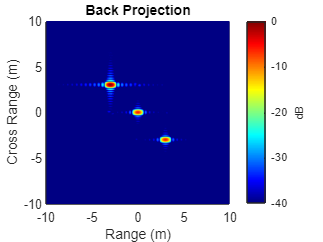

bpi = abs(bp_image) ./ max(max(abs(bp_image)));

figure;
pcolor(xi, yi, 20.0 * log10(bpi)); shading flat;
caxis([-abs(dynamic_range), 0.0])
h = colorbar;
ylabel(h, 'dB');

% Set the plot title and labels
title('Back Projection')
xlabel('Range (m)')
ylabel('Cross Range (m)')
axis('square')
colormap jet